# Control System II - CEP

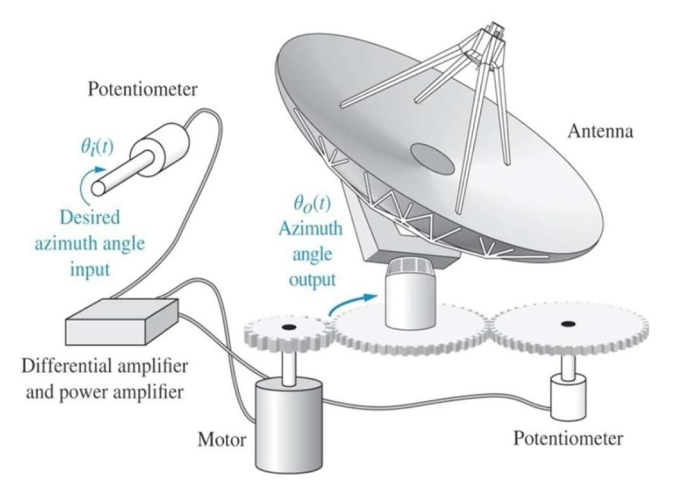

#### Note: -

In the Model the paramters those can be changed are deined using a Edit Field, thus can be changed but others are constants and can't be changed.

### Plant Definition

clear; clc; close all;

Definition of Plant using provided tranfer function and conversion of that tranfer function into state space.

sys_Tf=series(tf(1325,[1 0]),(series(tf(1,[1 1.7]),tf(1,[1 100]))))

sys_Tf =
 
           1325
  -----------------------
  s^3 + 101.7 s^2 + 170 s
 
Continuous-time transfer function.



[A,B,C,D]=tf2ss(sys_Tf.Numerator{1,1}, sys_Tf.Denominator{1,1})

A =  -101.7000 -170.0000         0
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =            0           0        1325


D = 0

[m,n]=size(A);

### Open Loop Plant Aalysis

Plant Controlability and Observeability Analysis in open loop to check whether the plat is conrolable and observeable, if not then there is no meaning to proceed with this type of plant.

P_c=ctrb(A,B);
P_o=obsv(A,C);
if(rank(P_c)==m)
    fprintf("The system is controlable as value of rank(P_c) = %d, which is full rank",rank(P_c));
else
    fprintf("The system is not controlable as value of rank(P_c) = %d, which is not full rank",rank(P_c));
end

The system is controlable as value of rank(P_c) = 3, which is full rank

if(rank(P_o)==m)
    fprintf("The system is observealable as value of rank(P_o) = %d, which is full rank",rank(P_o));
else
    fprintf("The system is not observealable as value of rank(P_o) = %d, which is not full rank",rank(P_o));
end

The system is observealable as value of rank(P_o) = 3, which is full rank

Here are the poles-zero plot of the plant in complex plane, here we can see that the plant is marginally stable as there is an integrator in it or in simple words a pole is lying on imagenary axis specifically saying on origin.

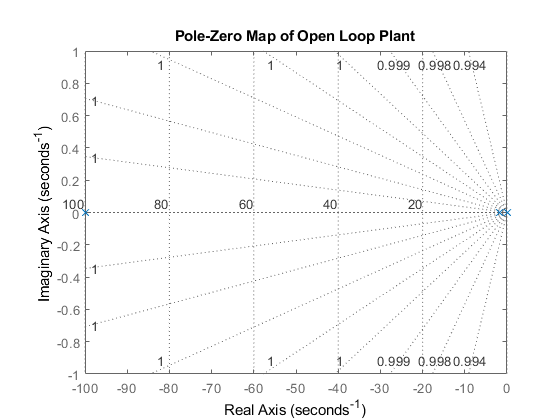

figure(1);
pzplot(sys_Tf);
grid on; grid minor;
title('Pole-Zero Map of Open Loop Plant');


disp("Poles of Open Loop Plant Model: -");

Poles of Open Loop Plant Model: -


plnt_pol=pole(sys_Tf)

plnt_pol =          0
 -100.0000
   -1.7000


### Control Specifications & Paramters

Defining the control specifications for the plant as required the Overshoot is less than 10% and Setteling Time is less than 1s.

OV=10;
T_s=1;

Here are the control parameters for the control specifications defined. The Natural Frequency can be found out from Setellign Time and Damping Ratio.

zeta=-log(OV/100)/sqrt(pi^2+log(OV/100));
fprintf("For overshoot <= %d%% the zeta >= %f",OV,zeta);

For overshoot <= 10% the zeta >= 0.837054

zeta=0.9; % Shoudl be >= 0.84
fprintf("Let's select zeta = %f", zeta);

Let's select zeta = 0.900000


w_n=4/(zeta*T_s);
fprintf("For Setelling-Time <= %ds the Natural-Frequency >= %frad/s",T_s,w_n);

For Setelling-Time <= 1s the Natural-Frequency >= 4.444444rad/s

w_n=10; % Shoudl be >= 4.5
fprintf("Let's select Natural-Frequency = %frad/s", w_n);

Let's select Natural-Frequency = 10.000000rad/s

For the defined control paramters we can find the close loop poles of the system those are named as Desired Poles here in this script. We can use second order model to find out the poles and third pole can then be placed atleast 5 times far than dominant poles on real axis. The equation is;


$$s^2 +2\zeta \omega_n s+\omega_n^2 =0$$


syms s;
second_order_approx=s^2+2*zeta*w_n*s+w_n^2==0;
root=simplify(solve(second_order_approx,{'s'}));
disp("Desired Poles for Full State Feedback Controller: -");

Desired Poles for Full State Feedback Controller: -


plnt_pol_des=[double(real(root(1)))+double(imag(root(1)))*1i;
    double(real(root(2)))+double(imag(root(2)))*1i;
    7*double(real(root(1)))]

plnt_pol_des =   -9.0000 - 4.3589i
  -9.0000 + 4.3589i
 -63.0000 + 0.0000i


clear s second_order_approx;

### Full State Control Design for Step Input

For above defined desired poles following gains can be used in the flll state feedback control. Here we used the pole placement method to find out the gains to obtain new poles.

disp("Full State Feedback Controller Gains: -");

Full State Feedback Controller Gains: -


K=place(A,B,plnt_pol_des)

K = 	1.0e+03 *

   -0.0207    1.0640    6.3000


Here is the gain that can be used as Tracking Gain so that the steady state error can be eliminated from the system. The tracking gain formula is derived in the report. See Appendix.

disp("Tracking Gain for Full State Feedback Controller: -");

Tracking Gain for Full State Feedback Controller: -


K_r=-1/(C*inv(A-B*K)*B)

K_r = 4.7547

Observer Poles need to be defined here the observer poles should atleast be 5 time far from the system close loop poles to obtain fast response from observer so that it can generate outptus faster than the system.

disp("Desired Poles for Full State Observer: -");

Desired Poles for Full State Observer: -


obsv_pol_des=10*plnt_pol_des;

disp("Full State Observer Gains: -");

Full State Observer Gains: -


L=place(A',C',plnt_pol_des)'

L =  -235.8397
    2.3918
   -0.0156


Step input parameters & Simulation of Simulink Model

step_start=0;
step_value=1;
step_ini_value=0;
step_stop_time=2;

% set_param('Full_State_Control__Step_Input', 'StopTime', string(step_stop_time));
out.step=sim("Full_State_Control__Step_Input.slx");

Output response of the Full State Feeback Control with Step input as reference signal. (Output Response, Plant Input, Error)

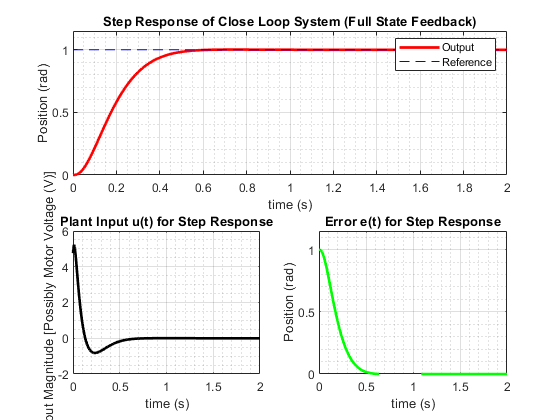

figure(2);
subplot(2,2,[1 2]);
plot(out.step.tout,out.step.fullStateOut(:,4),'-r','LineWidth',2);
hold on; grid on; grid minor;
plot(out.step.tout,out.step.fullStateOut(:,1),'--b','LineWidth',0.5);
hold off; legend('Output','Reference');
title('Step Response of Close Loop System (Full State Feedback)');
xlabel('time (s)'); ylabel('Position (rad)');
xlim([0 step_stop_time]); ylim([0 step_value+0.15*step_value]);

subplot(2,2,3);
plot(out.step.tout,out.step.fullStateOut(:,3),'-k','LineWidth',2);
grid on; grid minor;
title('Plant Input u(t) for Step Response');
xlabel('time (s)'); ylabel('Input Magnitude [Possibly Motor Voltage (V)]');
xlim([0 step_stop_time]);

subplot(2,2,4);
plot(out.step.tout,out.step.fullStateOut(:,2),'-g','LineWidth',2);
grid on; grid minor;
title('Error e(t) for Step Response');
xlabel('time (s)'); ylabel('Position (rad)');
xlim([0 step_stop_time]); ylim([0 step_value+0.15*step_value]);

### Full State Control Design using Internal Model for Ramp Input

The Internal Model in the form of State Space is defined for the ramp input signal.

A_bar=[0 1 zeros(1,m);
    0 0 C;
    zeros(m,1) zeros(m,1) A];
B_bar=[0;0;B];

Observer Poles can be defined from the poles defined for the previous system in the full state feedback control, for the undominant poles i.e. P3, P4, and P5, place them far from dominant ones.

disp("Desired Poles for Internal Model Controller for Ramp Input: -");

Desired Poles for Internal Model Controller for Ramp Input: -


plnt_pol_des_IM=[double(real(root(1)))+double(imag(root(1)))*1i;
    double(real(root(2)))+double(imag(root(2)))*1i;
    7*double(real(root(1)))+0.1*1i;
    7*double(real(root(1)))-0.1*1i;
    7.5*double(real(root(1)))]

plnt_pol_des_IM =   -9.0000 - 4.3589i
  -9.0000 + 4.3589i
 -63.0000 + 0.1000i
 -63.0000 - 0.1000i
 -67.5000 + 0.0000i


Internal Model gains defined using poles placement method, the desired poles are defined above.

K_IM=place(A_bar,B_bar,plnt_pol_des_IM);

disp("Internal Model Control with Ramp Input Gains: -");

Internal Model Control with Ramp Input Gains: -


K_1=K_IM(1)

K_1 = 2.0219e+04

K_2=K_IM(2)

K_2 = 4.5809e+03

K_3=K_IM(3:end)

K_3 = 	1.0e+05 *

    0.0011    0.1589    5.1179


Ramp input parameters & Simulation of Simulik Model

ramp_start=0;
ramp_slope=1;
ramp_ini_value=0;
ramp_stop_time=2;

% set_param('Internal_Model_Control__Ramp_Input', 'StopTime', string(ramp_stop_time));
out.ramp=sim("Internal_Model_Control__Ramp_Input.slx");

Output response of the Internal Model Control with Ramp input as reference signal. (Output Response, Plant Input, Error)

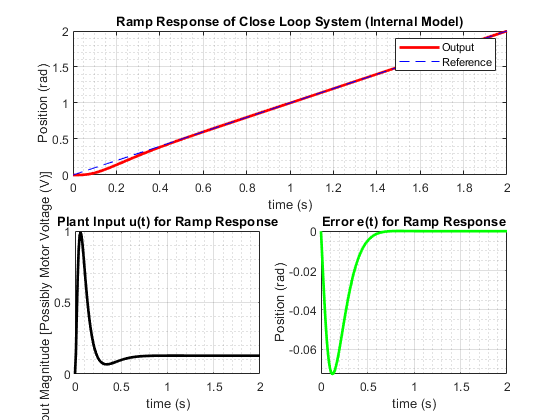

figure(3);
subplot(2,2,[1 2]);
plot(out.ramp.tout,out.ramp.internalModelOut(:,4),'-r','LineWidth',2);
hold on; grid on; grid minor;
plot(out.ramp.tout,out.ramp.internalModelOut(:,1),'--b','LineWidth',0.5);
hold off; legend('Output', 'Reference');
title('Ramp Response of Close Loop System (Internal Model)');
xlabel('time (s)'); ylabel('Position (rad)');
xlim([0 ramp_stop_time]); ylim([0 out.ramp.tout(end)*ramp_slope]);

subplot(2,2,3);
plot(out.ramp.tout,out.ramp.internalModelOut(:,3),'-k','LineWidth',2);
grid on; grid minor;
title('Plant Input u(t) for Ramp Response');
xlabel('time (s)'); ylabel('Input Magnitude [Possibly Motor Voltage (V)]');
xlim([0 ramp_stop_time]);

subplot(2,2,4);
plot(out.ramp.tout,out.ramp.internalModelOut(:,2),'-g','LineWidth',2);
grid on; grid minor;
title('Error e(t) for Ramp Response');
xlabel('time (s)'); ylabel('Position (rad)');
xlim([0 ramp_stop_time]);